***Q5 (c) *****MTH739U / MTH739P: Topics in Scientific Computing 2019/20 – Coursework 1 **

**Top Level Summary**

A parametric plot of the Lorenz equation is produced with n = 30000 points.

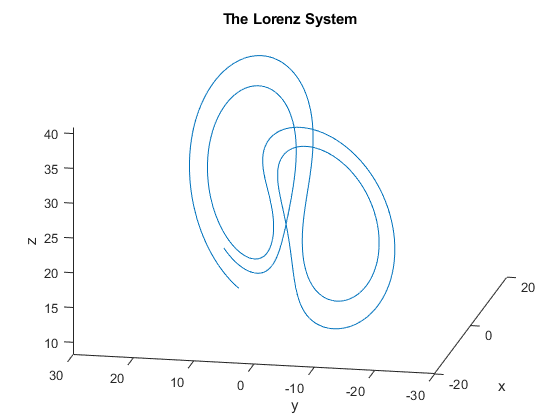

T0 = 0;               %Initial Time
T = 3;                %Final Time
n = 30000;           %number of points. 
dt = ((T-T0)/(n-1)); 
sigma   = 11;
beta    = 3;
rho     = 27;
x0      = 5.0;
y0      = 10.0;
z0      = 10.0;
x(1)    = x0;
y(1)    = y0;
z(1)    = z0;

ay = 0;
az = 0;

x_dot   = @(sigma,x,y)      sigma*(y-x);
y_dot   = @(rho,x,y,z)      x*(rho-z)-y;
z_dot   = @(beta,x,y,z)     x*y-beta*z;

for i = 1:n-1
    
    ax = x_dot(sigma,   x(i),           y(i));
    bx = x_dot(sigma,   x(i)+ax*dt/2,   y(i)+ay*dt/2);
    cx = x_dot(sigma,   x(i)+bx*dt/2,   y(i)+ay*dt/2);
    dx = x_dot(sigma,   x(i)+cx*dt,     y(i)+ay*dt);
        
    ay = y_dot(rho,     x(i),           y(i),           z(i));
    by = y_dot(rho,     x(i)+ax*dt/2,   y(i)+ay*dt/2,   z(i)+az*dt/2);
    cy = y_dot(rho,     x(i)+bx*dt/2,   y(i)+by*dt/2,   z(i)+az*dt/2);
    dy = y_dot(rho,     x(i)+cx*dt,     y(i)+cy*dt,     z(i)+az*dt);
     
    az = z_dot(beta,    x(i),           y(i),           z(i));
    bz = z_dot(beta,    x(i)+ax*dt/2,   y(i)+ay*dt/2,   z(i)+az*dt/2);
    cz = z_dot(beta,    x(i)+bx*dt/2,   y(i)+by*dt/2,   z(i)+bz*dt/2);
    dz = z_dot(beta,    x(i)+cx*dt,     y(i)+cy*dt,     z(i)+cz*dt);
     
    x(i+1) = x(i) + (ax + 2*bx + 2*cx + dx)*dt/6;
    y(i+1) = y(i) + (ay + 2*by + 2*cy + dy)*dt/6; 
    z(i+1) = z(i) + (az + 2*bz + 2*cz + dz)*dt/6;

end
plot3(x,y,z)
title('The Lorenz System')
xlabel('x')
ylabel('y')
zlabel('z')